clear; clc; close all;
dirname = 'Dataset/';

training = imageDatastore(dirname,'IncludeSubfolders',true); % 'Dataset/'
training.Files = natsortfiles(training.Files);

bboxes = bboxtable('train_matlab.csv');
blds = boxLabelDatastore(bboxes);

cds = combine(training,blds);

## Random Samples

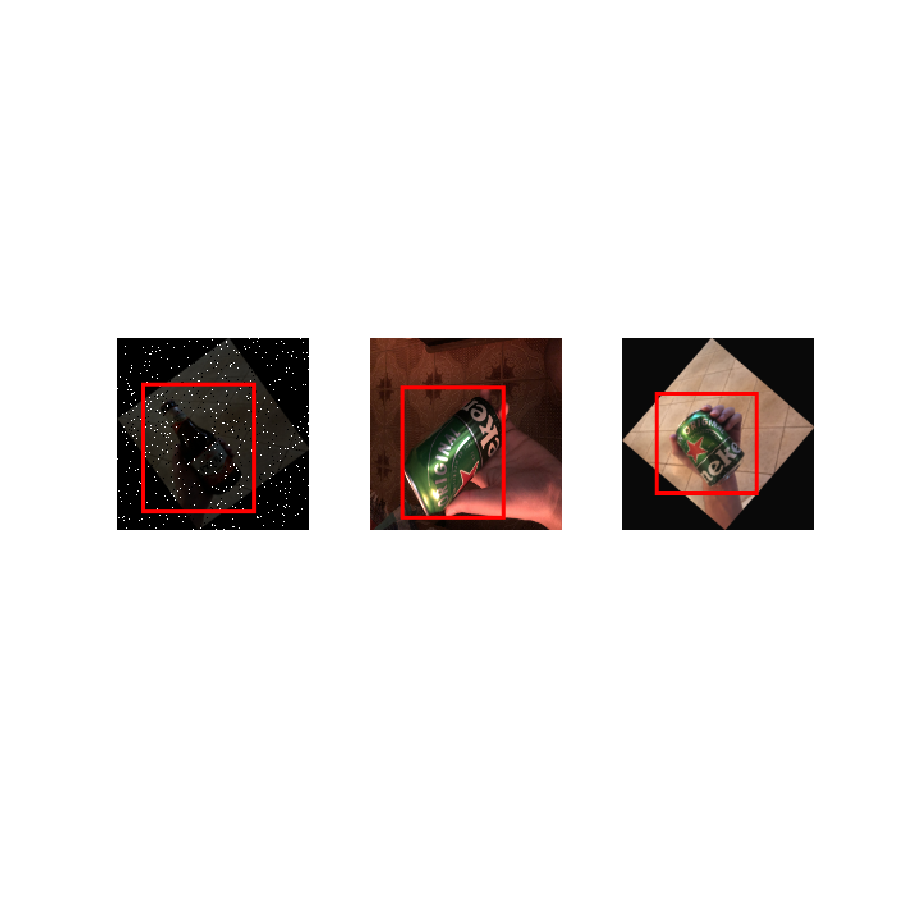

samples = randperm(size(training.Files,1),3);
fig = figure('Renderer', 'painters', 'Position', [0 0 900 900]);

for x = 1:length(samples)
    img = imread(training.Files{samples(x)});
    
    subplot(1,3,x), imshow(img), hold on;
    rectangle('Position',blds.LabelData{samples(x)},'EdgeColor','r','LineWidth',3);
end

preprocds = transform(cds,@(data)preprocessData(data,[150 150 3]));
numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocds,numAnchors);
disp(anchorBoxes);

   101    85
    62    66
    82   121



## Set Network arctecture

net = resnet50;

lgraph = layerGraph(net);

% Change input size
inputLayer = imageInputLayer([150,150,3],'Name','ImageInput');
lgraph = replaceLayer(lgraph,'input_1',inputLayer);

% Define layers to be removed
layersToRemove = {'fc1000' 'fc1000_softmax' 'ClassificationLayer_fc1000'};
lgraph = removeLayers(lgraph,layersToRemove);

numClasses = 7;
numClassesPlusBackground = numClasses + 1;
newLayers = [fullyConnectedLayer(numClassesPlusBackground, 'Name', 'rcnnFC')
    softmaxLayer('Name', 'rcnnSoftmax')
    classificationLayer('Name', 'rcnnClassification')
];

lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph, 'avg_pool', 'rcnnFC');

% Regression layer parameters
numOutputs = 4 * numClasses;
boxRegressionLayers = [fullyConnectedLayer(numOutputs,'Name','rcnnBoxFC')
    rcnnBoxRegressionLayer('Name','rcnnBoxDeltas')
];

lgraph = addLayers(lgraph, boxRegressionLayers);
lgraph = connectLayers(lgraph,'avg_pool','rcnnBoxFC');

% Activation map
featureExtractionLayer = 'activation_40_relu';

lgraph = disconnectLayers(lgraph, featureExtractionLayer,'res5a_branch2a');
lgraph = disconnectLayers(lgraph, featureExtractionLayer,'res5a_branch1');

% Add ROI max pooling layer.
outputSize = [10 10];
roiPool = roiMaxPooling2dLayer(outputSize,'Name','roiPool');
lgraph = addLayers(lgraph, roiPool);

% Connect feature extraction layer to ROI max pooling layer.
lgraph = connectLayers(lgraph, featureExtractionLayer,'roiPool/in');

% Connect the output of ROI max pool to the disconnected layers from above.
lgraph = connectLayers(lgraph, 'roiPool','res5a_branch2a');
lgraph = connectLayers(lgraph, 'roiPool','res5a_branch1');

## Region Proposal Network

% Define anchor boxes.
% anchorBoxes = [305 406
%     360 290
%     216 237
% ];

% Create the region proposal layer.
proposalLayer = regionProposalLayer(anchorBoxes,'Name','regionProposal');

lgraph = addLayers(lgraph, proposalLayer);

%% convolution layers for RPN
% Number of anchor boxes.
numAnchors = size(anchorBoxes,1);

% Number of feature maps in coming out of the feature extraction layer. 
numFilters = 1024;

rpnLayers = [convolution2dLayer(3, numFilters,'padding',[1 1],'Name','rpnConv3x3')
    reluLayer('Name','rpnRelu')
];

lgraph = addLayers(lgraph, rpnLayers);

% Connect to RPN to feature extraction layer.
lgraph = connectLayers(lgraph, featureExtractionLayer, 'rpnConv3x3');

%% Add RPN classification layers
rpnClsLayers = [
    convolution2dLayer(1, numAnchors*2,'Name', 'rpnConv1x1ClsScores')
    rpnSoftmaxLayer('Name', 'rpnSoftmax')
    rpnClassificationLayer('Name','rpnClassification')
    ];
lgraph = addLayers(lgraph, rpnClsLayers);

% Connect the classification layers to the RPN network.
lgraph = connectLayers(lgraph, 'rpnRelu', 'rpnConv1x1ClsScores');

%% Add RPN regression layers.
rpnRegLayers = [
    convolution2dLayer(1, numAnchors*4, 'Name', 'rpnConv1x1BoxDeltas')
    rcnnBoxRegressionLayer('Name', 'rpnBoxDeltas');
    ];

lgraph = addLayers(lgraph, rpnRegLayers);

% Connect the regression layers to the RPN network.
lgraph = connectLayers(lgraph, 'rpnRelu', 'rpnConv1x1BoxDeltas');

% Connect region proposal network.
lgraph = connectLayers(lgraph, 'rpnConv1x1ClsScores', 'regionProposal/scores');
lgraph = connectLayers(lgraph, 'rpnConv1x1BoxDeltas', 'regionProposal/boxDeltas');

% Connect region proposal layer to roi pooling.
lgraph = connectLayers(lgraph, 'regionProposal', 'roiPool/roi');

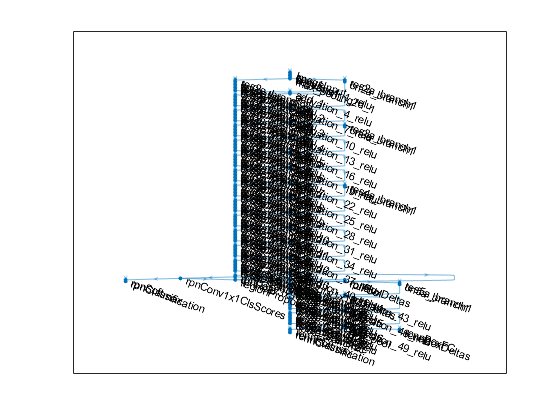

figure; plot(lgraph);

## Train Faster R-CNN

miniBatchSize = 4;
valFrequency = floor(numel(training.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4, ...
    'Verbose',true, ...
    'MiniBatchSize',miniBatchSize, ...
    'VerboseFrequency', valFrequency, ...
    'CheckpointPath','checkpoints/n2')

options =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-04
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 10
                MiniBatchSize: 4
                      Verbose: 1
             VerboseFrequency: 347
               ValidationData: []
          ValidationFrequency: 50
           ValidationPatience: Inf
                      Shuffle: 'once'
               CheckpointPath: 'checkpoints/n2'
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'none'
               SequenceLength: 'longest'
         SequencePaddingValue: 0
     SequencePaddingDirection: 'right'
         DispatchInBackground: 0
      Rese

trainedDetector = trainFasterRCNNObjectDetector(preprocds,lgraph,options, ...
        'NegativeOverlapRange',[0 0.3], ...
        'PositiveOverlapRange',[0.6 1]);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* BudweiserLata
* BudweiserLongNeck
* HeinekenLata
* HeinekenLongNeck
* PetraLata
* PetraLongNeck
* StellaArtoisLongNeck

Training on single GPU.
Initializing input data normalization.
|=============================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |      Rate       |
|=============================================================================================================================================|
|       1 |           1 |       00:00:02 |      10.0214 |       31.05% |         2.42 |   